# Day 1: Genome-scale models in MATLAB

## Learning goals

- Add new reactions to an existing GEM to facilitate synthesis of a product of interest

- Calculate maximum biochemical yields

- Interpret production envelope and phenotypic phase plane plots

- Perform FSEOF and interpret the results

- Perform optKnock and interpret the results

## 1. Add reactions and simulate production

For this exercise we will study the production of biliverdin in *E. coli*. Biliverdin is a derivative from heme, and has a wide range of potential protective effects, including as anti-mutagenic and antioxidant. Heme oxygenase catalyses the reaction of biliverdin from heme, releasing iron and carbon monoxide. While *E. coli* is not a native producer of biliverdin, overexpression of a gene from the cyanobacteria *Synechocystis* spp. allows for the reaction below:

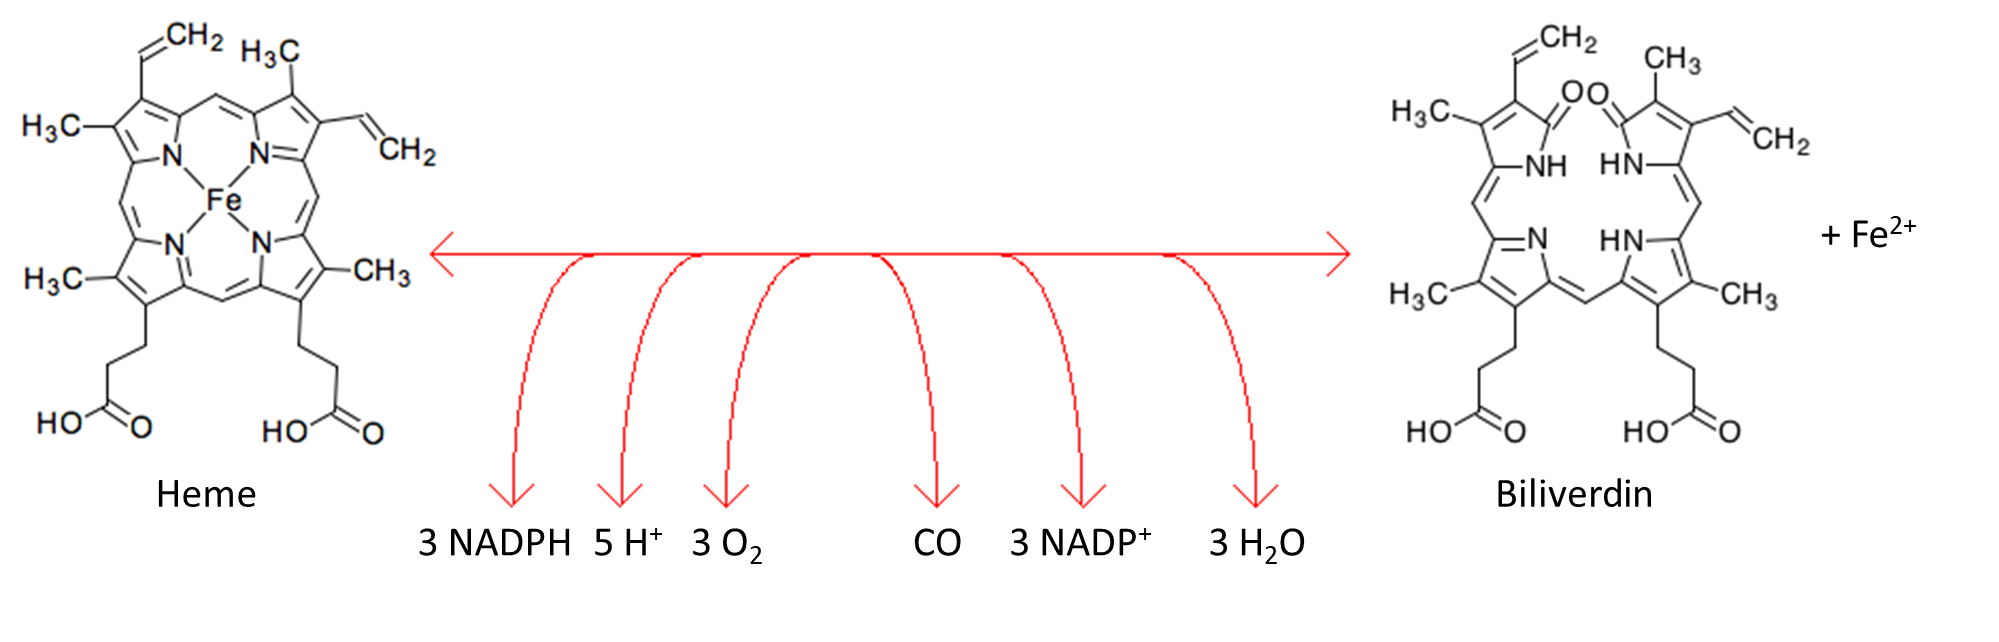

We will introduce this reaction and do some analyses around its production. But first we will load the genome-scale model of *E. coli*. 

clear;clc % Clear the command window and workspace
model = importModel('iECD_1391.xml');

### 1.1 Add the required reactions

When new reactions are added, it is essential that no unnecessary duplicate metabolites are added. After checking which metabolites are already present in the model (and noting down their metabolite identifier), it transpires that not only biliverdin, but also carbon monoxide is not yet present in the model. These need to be added. But in which compartments? The model has three compartments:

disp(model.compNames)

We will assume that carbon monoxide can diffuse through the periplasmic membrane and is thereby excreted (and an exchange reaction is added). Biliverdin mostly remains intracellular, but to allow it to accumulate we add an exchange reaction that directly uses the cytoplasmic biliverdin.

We first add the metabolites as following, with unique metabolite identifiers. For simplicity we leave out a lot of additional data, for instance the chemical formula, the charge, and annotation to other databases (KEGG; MetaCyc etc.). None of this information is required to add the metabolites:

metsToAdd.mets         = {'co_c','co_p','co_e','biliverdin_c',};
metsToAdd.metNames     = {'carbon monoxide','carbon monoxide','carbon monoxide','biliverdin'};
metsToAdd.compartments = {'c','p','e','c'};
model = addMets(model,metsToAdd);

Next, we add the heme oxygenase reaction, plus the required transport and exchange reactions:

rxnsToAdd.rxns      = {'HEMEOX','EX_biliverdin','COtpp','COtex','EX_co'};
rxnsToAdd.equations = {'pheme_c + 3 nadph_c + 5 h_c + 3 o2_c => biliverdin_c + fe2_c + co_c + 3 nadp_c + 3 h2o_c',...
                       'biliverdin_c =>','co_c <=> co_p','co_p <=> co_e','co_e <=>'};
model=addRxns(model,rxnsToAdd);

And finally we set a few constraints and ensure that biomass is set as the objective function:

model = setParam(model,'lb','EX_glc',-10);
model = setParam(model,'lb','EX_o2',-20);
model = setParam(model,'obj','EX_biliverdin',1);
% Export for use in other scripts
exportModel(model,'iECD_1391_biliverdin.xml');

### 1.2 Calculate maximum biochemical yield

While taking into consideration the maximum glucose uptake defined above, what is the maximum biochemical yield of biliverdin? This can be calculated by setting biliverdin exchange as the objective function:

model = setParam(model,'obj','EX_biliverdin',1);
FBAsolution = solveLP(model);
fprintf(['Maximum biliverdin production is: ' num2str(FBAsolution.f) '\n'])

**Question 1: What is the maximum biochemical biliverdin yield in *****E. coli*****? (Think about the units!)**

### 1.3 Plot production envelope

With the code below, plot the production envelope.

model = setParam(model,'obj','EX_biliverdin',1);
targetRxn   = 'EX_biliverdin';
biomassRxn  = 'Ec_biomass_iJO1366_core_53p95M';
nPts        = 25; % Number of steps to make
[biomassValues,targetValues] = runProductionEnvelope(model,targetRxn,biomassRxn,nPts);

**Question 2: Describe what you see in the graph.**

You have now seen how you can take an existing model and modify it to simulate the synthesis of an heterologous product. While it is relatively straightforward how to implement this, there are a few critical points that need to be considered. Imagine you work on a project where you have identified a gene cluster responsible for the production of a new plant secondary metabolite. You don't know exactly what each gene in the cluster is doing, but you know that together they make this interesting secondary metabolite. You plan to just express the whole gene cluster in yeast, as you anticipate that this would constitute the whole biosynthetic pathway that is required. You also want to determine what the maximum biochemical yield would be in yeast. 

**Question 3: What challenges will you encounter when you add the required reactions to the model?**

## 2. Dynamic flux balance analysis (dFBA)

HEMEOX is a heterologous reaction for which we express a gene from *Synechocystis*, and the activity of this reaction can be modified by e.g. changing the promoter sequence in front of the gene. In the model we can simulate this by changing the bounds of the HEMEOX reaction, and here we will observe the effect of this on the biliverdin titer that is reached during a batch cultivation. We will do this via dynamic FBA. The model has already been loaded to answer the previous questions, however, we might have made some changes (for instance increased lower bounds). To avoid potential confusion, we will first clear the results etc. from the previous questions and reload the model.

clear;clc % Clear the command window and workspace
model = importModel('iECD_1391_biliverdin.xml');

### 2.1 Set parameters for dynamic FBA

With 200 mM of glucose, we will simulate the production of biliverdin over 5 hours. For this, various parameters needs to be set.

substrateRxns      = 'EX_glc'; % Specify which substrate in the growth will
% have its concentration changed in the dFBA simulation.
initConcentrations = 200; % Initial amount of glucose (in mmol/L)
initBiomass        = .01; % Initial amount of biomass (in g/L)
timeStep           = .25; % Length of each time-step (in h)
nSteps             = 20; % Number of time-steps
% 20 steps at 0.25 hours is 5 hours
plotRxns           = 'EX_biliverdin'; % Select with reactions to plot
exclUptakeRxns     = {'EX_co2','EX_o2','EX_h2o','EX_h','EX_nh4','EX_pi','EX_so4','EX_k'};
% Specify which exchange metabolites should *not* have their concentration
% change in the growth medium (in contrast to glucose). These are gases and
% nutrients that we assume are not in limiting amounts.
model              = setParam(model,'obj','EX_biomass',1);
% Ensure we set growth as objective function, because during the batch
% cultivation we assume that the cells will attempt to follow their
% evolutionary objective: to grow as fast as possible.

### 2.2 Run dFBA at low HEMEOX activity

We will force a flux of 0.1 mmol/gDCW/h through the heme oxygenase reaction, if we would not do that, the model would not make any biliverdin (see the production envelope in Question 2).

model = setParam(model,'lb','HEMEOX',0.1); 

Run dFBA with the code below.

**Question 4: Describe the biliverdin titer and yield. Is the yield the same as the maximum biochemical yield? If not, why not?**

% Run FBA and make plot
[concentrationMatrix,excRxnNames,timeVec,biomassVec] = runDynamicFBA(model,substrateRxns,initConcentrations, initBiomass, timeStep, nSteps, plotRxns, exclUptakeRxns );
figure
pos = ismember(excRxnNames,'EX_glc');
plot(timeVec,concentrationMatrix(pos,:));
title('Glucose[e]'); xlabel('Time (h)'); ylabel('Concentration (mmol/L)');
fprintf('Residual glucose concentration: %f\n',concentrationMatrix(pos,end))

### **2.3 Run dFBA at higher HEMEOX activities**

Now simulate a situation where the HEMEOX gene would have had a higher expression level. Higher expression does not necessarily result in a higher flux through the reaction, but for simulation purposes we will increase the lower bound of HEMEOX to 0.5 mmol/gDCW/h. You should prepare the code yourself.

% Copy-paste some of the code that was used to run the first dFBA
% simulation. Modify this code to force a HEMEOX flux of 0.5. Repeat the
% dFBA and compare the titers and yields with what was reached in the
% previous dFBA simulation.

**Question 5: Compare and comment on the final biliverdin titers and yields that are reached with a minimum HEMEOX flux of 0.1 mmol/gDCW/h (in Question 4) and 0.5 mmol/gDCW/h (this question). **

### 2.4 Scan a range of HEMEOX activities

Let's explore a range of HEMEOX activities and see if the biliverdin titer and yield will always increase. Use the following code which runs dFBA multiple times, with increasing lowerbounds of the HEMEOX reaction.

x = 0; % Keep track of biliverdin production rates
% Note that the loop below will generate a plot during each iteration, but
% only the last one will be shown once the loop is finished.
for i=1:20 % Run 20 iterations
    x = x + 0.05; % Increase the reaction bound by 0.05 in each iteration
    model = setParam(model,'lb','HEMEOX',x);
    [concentrationMatrix,excRxnNames,timeVec,biomassVec] = ...
    runDynamicFBA(model,substrateRxns,initConcentrations, initBiomass, timeStep, nSteps, plotRxns, exclUptakeRxns );
    [a,loc] = ismember('EX_biliverdin',excRxnNames);
    prodTime(i,1) = x;
    bioProd(i,1) = max(concentrationMatrix(loc,:));
end
% Make a plot showing the HEMEOX lower limit and the biliverdin
% concentration reached in the cultivations.
figure(2);
plot(prodTime, bioProd)
title('Biliverdin Production'); xlabel('HEMEOX flux (mmol/(gDW h))'); ylabel('Concentration (mmol/L)');

**Question 6: At what HEMEOX activity do we get the highest biliverdin production? Can you explain what is causing this?**

## 3. Run FSEOF for overexpression targets

If you have expressed HEMEOX in *E. coli* and observed some production, what genes should you overexpress to further increase its production? The FSEOF (for "flux scanning based on enforced objective flux") algorithm identifies how reaction fluxes correlate to a shift from producing biomass towards more production of your preferred product (as biomass and product formation compete for the same carbon uptake). Again clear all memory and reload the model.

clear;clc % Clear the command window and workspace
model = importModel('iECD_1391_biliverdin.xml');

### 3.1 Run FSEOF

We will here run FSEOF for biliverdin production and inspect the output file (either in a text editor or in Excel). The 'slope' indicates how strongly the flux through a reaction is coupled to increased biliverdin production. Note that the reactions directly involved with biliverdin have a slope of 1, if a slope is more than 1 than this indicates that this reaction should run multiple times to produce one biliverdin. A higher slope is therefore suggesting which reactions are carrying most flux for biliverdin production: potential overexpression targets. Under 'direction' is indicated for reversible reactions whether the flux through the reaction is in the forward direction (1) or reverse direction (-1). If a reaction is irreversible, a 0 is reported.

biomassRxn = 'EX_biomass';
targetRxn  = 'EX_biliverdin';
iterations = 10;
coefficient= 0.9; % What should be the maximum biochemical yield to be
% simulated. 0.9 refers to 90%.
outputFile = 'FSEOF_biliverdin.tab';
FSEOF(model,biomassRxn,targetRxn,iterations,coefficient,outputFile)

A number of reactions have a slope close to 8. Look at the pathways involved in heme biosynthesis here: [https://ecocyc.org/ECOLI/NEW-IMAGE?type=PATHWAY&object=PWY0-1415](https://ecocyc.org/ECOLI/NEW-IMAGE?type=PATHWAY&object=PWY0-1415) and [https://ecocyc.org/ECOLI/NEW-IMAGE?type=PATHWAY&object=PWY-5188](https://ecocyc.org/ECOLI/NEW-IMAGE?type=PATHWAY&object=PWY-5188).

**Question 7: Can you explain why some of the reactions have a slope of around 8? Why are these slopes not *****exactly***** 8? Think about how the FSEOF algorithm works.**

## 4. optKnock for knockout targets

To find knockout targets that can improve production (by ensuring growth coupling), you can use e.g. optKnock. We will not use it here on the production of biliverdin, because in this model there are no combination of 3 knockouts that can result in growth-coupled biliverdin production (perhaps there are with larger number of knockouts, but we have only tested upto 3 simulatenous knockouts, because it otherwise takes too long to run).

Instead, we will look at the production of **acetate**, **succinate** and **formate**, as for these three products there are single knockouts that can result in growth-coupled production.

The algorithm that we will use in this exercise is also not the real optKnock algorithm. The `runSimpleOptKnock` algorithm runs FBA for each knockout one at a time, which is a brute force approach and takes very long if you want to test all possible combinations of multiple knockouts. On the plus side, it is relatively easy to run and it works with the free glpk solver that is provided with RAVEN. It also works on the level of reactions instead of genes (which would be more accurately replicating a real knockout), as this is also easier to implement. The text here will refer to "knockout of reactions", but in reality it would be genes that are knocked out.

To further speedup the `runSimpleOptKnock` function, we will not knockout reactions that:(a) are essential (their knockout would not allow growth); (b) never carry any flux (their knockout would not have an effect); (c) are closely related to biomass production (their knockout is less likely to affect the production of a *simple *metabolic intermediate); (d) are transport and exchange reactions; etc. In the end, we will knockout 195 reactions, one by one.

clear;clc % Clear the command window and workspace
model = importModel('iECD_1391.xml');
load('knockout_SelectedRxns.mat','selectedRxns'); % Load list of 195 reactions selected for knockout

### 4.1 Run simple optKnock analysis

As described above, there are three metabolites with exchange reactions for which a single reaction knockout results in growth-coupled production. Below is the code to analyze this for succinate:

KOnumber   = 1; % Maximum number of simulatenous knockouts to try. Increasing
% this will exponentially increase the running time. If it takes ~3 sec to
% run for 195 reactions, it will take ~6.5 minutes for 195x195 reactions,
% and 32 hours for 195x195x195. Let's start with one KO.
targets = runSimpleOptKnock(model, 'EX_succ', 'EX_biomass', selectedRxns, 'rxns', KOnumber);

The above will knockout each reaction in the `selectedRxns` list one-by-one, and test if the knockout results in growth-coupled production. The `targets` structure contains the results, and for succinate there is only one reaction that enabled growth-coupled production. In `targets`, `KO` specifies which reactions are knocked out in each of the results, `growthRate` and `prodRate` are the corresponding growth and production rates. `score` is derived from multiplying the growth and production rates of each result: a high score gives high production without a drastic decrease in growth. Below, we will see that the maximum growth rate has decreased in the knockout strain, by comparing the growth in the `targets` structure with the growth rate that is reached in the unchanged model.

struct2table(targets)
% For comparison, here is the growth rate without knockouts
sol = solveLP(model);
fprintf('Growth rate without knockouts: %f',sol.f)

### 4.2 Confirm with production envelope

To confirm that the above mentioned reaction knockout has resulted in growth-coupled production, this should be visible in a production envelope plot:

modelSucc = setParam(model,'eq',targets.KO(1),0); % Knockout the first target.
% Here the reaction identifier is directly taken from targets.KO, but you
% could also directly define the reaction identifier instead.
% Make the production envelope as we have done previously:
runProductionEnvelope(modelSucc,'EX_succ','EX_biomass',50);

**Question 8: How does the production envelope show that there is growth-coupled production?**

Having visually confirmed that this knockout results in growth-coupled production, you could inspect the fluxes with and without the knockout, trying to figure out what exactly causes the growth coupling. [However, this is not so straight forward, but feel free trying to figure it out!]

### 4.3 Further improvement?

It is possible that additional knockouts result in further improvement of the growth coupling (where improvement refers to the *score*: growth rate multiplied by production rate). It would be even better to consider all double knockouts, because maybe the best performing double knockout does not include the gene that you found above? However, to evaluate all double knockouts greatly increases the running time of the `runSimpleOptKnock` function, as described above. The best solution would therefore be to use a more advanced algorithm like [OptGene](https://bmcbioinformatics.biomedcentral.com/articles/10.1186/1471-2105-6-308) (which is implemented in [COBRA Toolbox](https://opencobra.github.io/cobratoolbox/stable/tutorials/tutorialOptGene.html)).

To still being able to show some calculations in this exercise, let's implement the knockout that was found above, and we can rerun the `runSimpleOptKnock `algorithm on the model where the previous target is already knocked out. It will then not try out all combinations, but maybe still result in some improvement. Note that this is not the best approach to find beneficial double-knockouts, as it might be that these knockouts are only beneficial when performed simultaneously without having an effect when implemented individually. Regardless, let's give it a try here:

% We reuse the model that we also used to draw the production envelope, so
% that the previously found target is already knocked out. Then we rerun
% runSimpleOptKnock to find any additional knockouts
targets2 = runSimpleOptKnock(modelSucc, 'EX_succ', 'EX_biomass', selectedRxns, 'rxns', 1);
% Let's inspect if a target is found
struct2table(targets2)
% The table is empty

It seems that once the earlier target gene is knocked out, there is no second knockout that will improve the growth-coupled production. But let's not give up yet, and look at 3 simultaneous knockouts instead. As this would take more than 30 hours with the code that we have used up to know, let's make it a little faster by drastically reducing the number of reactions that are allowed to be knocked out. [This is of course cheating: we previously ran an hours-long simulation to make sure that the list of reactions includes those that are beneficial when knocked out together].

selectedRxns = {'PSP_L'; 'FUM'; 'PYK'; 'PDH'; 'POR5'; 'ENO'; 'HEX1'; 'PGI';...
    'PFK'; 'FBA'; 'TPI'; 'PGK'; 'PGM'; 'LDH_D'; 'PFL'; 'ACKr'; 'GNK'; 'PGCD'};
% We run this on the original model, without any knockouts yet.
targets3 = runSimpleOptKnock(model,'EX_succ','EX_biomass',selectedRxns,'rxns',3);

Let's inspect the results:

targetsTable = struct2table(targets3) % We keep the output in targetsTable, so that we can show a subset of this table later

You will notice that the `runSimpleOptKnock` function was not that well written, as the output has duplicate entries when multiple genes are knocked out. The same genes are knocked out in row 2 and row 6. So while the table has 46 rows, there are actually less unique sets of beneficial knockouts.

Let's look at the best scoring knockout sets

topScore = max(targets3.score); % Get the highest score
topSets = find(targets3.score == topScore); % There are multiple sets with this same score
% Now we can use this to subset from the earlier table
targetsTable(topSets,:)

If you inspect this list, you see that there are two sets of 3 knockouts.

Compare the score that is reached by these triple knockouts, with the score that was reached when only 1 reaction was knocked out (in section 4.2).

Now also compare the production envelope. Note that the x-axis is automatically adjusted, which somewhat complicates it when you want to compare two different production envelope plots. Keep this in mind when you compare the two plots on the screen. You might find it helpful to sketch them on paper (with the same x-axis), or maybe you are comfortable to adjust MATLAB parameters instead.

% Copy-paste the code from section 4.2 and adapt to knockout one of the
% subsets of three reactions. Instead of directly using the reaction
% identifiers from the targetsTable, it may be easier to directly mention
% which reactions should be blocked by setParam.

**Question 9: Describe how the production envelope has changed comparing the triple knockout with the earlier single knockout. Is the optimal solution that is reached after the triple knockout also part of the solution space in the single knockout?**

## Other targets

If you're done, you could repeat the above for formate, instead of succinate. Similar results will be obtained, although with different knockouts.